# **LABX_blinkArduino**

------------------------------------------------------------------------------------------------------------------------------------------------------

Created: 4 May 2018

By: Samuel Bechara, PhD

## Introduction

In this lab, we will setup the Arduino in MATLAB. Before we start, it is important to remember that Arduinos are great for giving tasks but we need to be careful of what those tasks are. We need to make sure we understand **how to tell MATLAB to talk to the Arduino**.

**There will be 3 main steps:**

- **Download and install the support packages**. MATLAB is already a monster of a program. Mathworks says you can expect 3-4gb in a typical installation. To save space, the functionality to program an Arduino is not included in the base installation.

- We need to **tell MATLAB we want to talk to the Arduino**. To do that, we create an Arduino object. Since Arduinos do what we tell them to do, I recommend giving them names that suggest what you want it to do. Think of Arduino, sitting at a restaurant, waiting for you. It's fancy, so you need to tall the Matier D' you would like to be sat with Arduino so you guys can talk. Business or Love? I guess you decide.

- **Learn Arduino-Matlab-ese**. The weird thing about Arduinos is that they can speak a couple of different languages. The majority of the code you see online for Arduinos will be written in "Arduino programming language" but we will be talking MATLAB. Its all aces, we already speak MATLAB and there is no code online to copy*! 

** I acknowledge that my pros/cons list may look different than yours.*

## Step 1) Download Support Package

*Step 1.1*) In the "HOME" tab on the main page click the Add-Ons button.

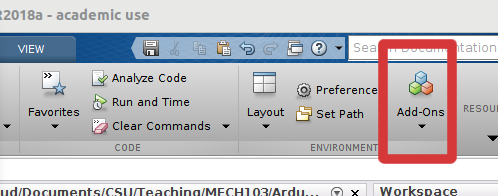

*Step 1.2*) In the window that pops up, search for Arduino and install the "MATLAB Support Package for Arduino Hardware" by clicking the text highlighted below.  Make sure you have your Arduino with a USB cable handy.

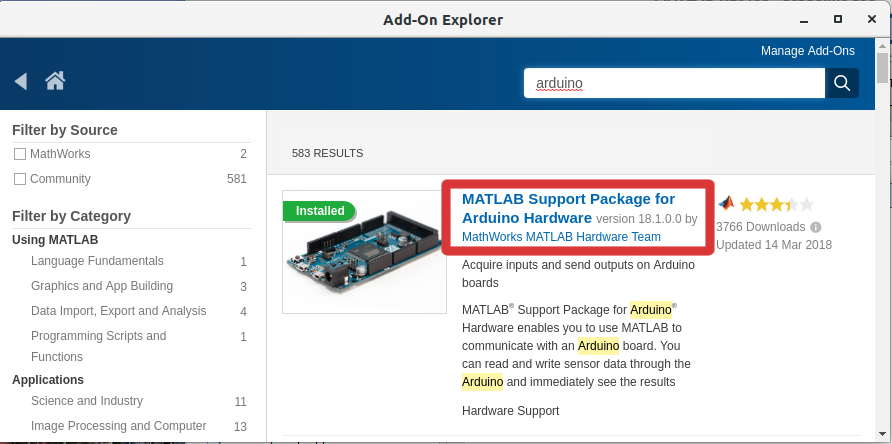

*Step 1.3*) Next where mine says, "Learn More" and "Manage" highlighted below, you should have an option to install. **Begin the installation procedure by clicking install.** When you are all finished, you should see these buttons. This Manage button is how you can restart the automatic setup wizard that begins after installation (hence needing the USB cable handy).

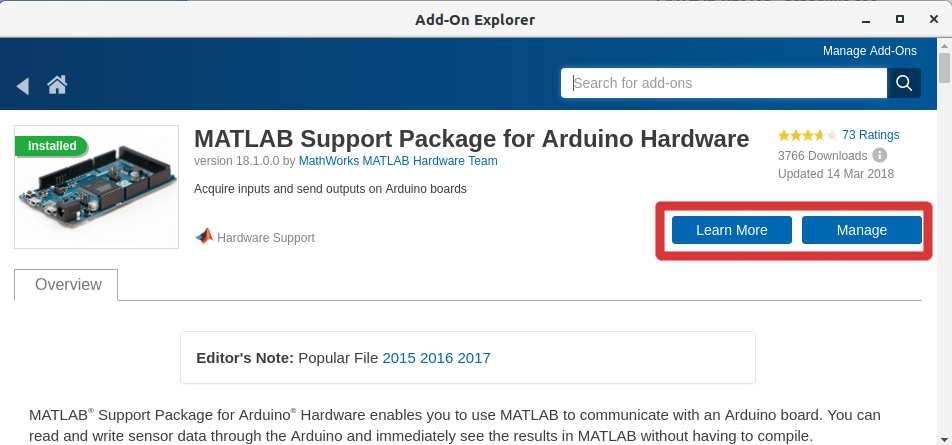

## Step 2) Follow the automated setup wizard

The MATLAB Arduino setup wizard will install software onto the arduino so that the Arduino can talk to MATLAB. It is pretty straightforward and easy to use. If you are using Linux, you need to make sure that your permissions are setup correctly. It is critical to note, you can re-enter the arduino setup wizard at any time by typing:

arduinosetup % command will launch the arduino setup wizard

into the command window. You MAY need to do this at a later time so don't forget this!

*Step 2.1*) **Follow the automated setup wizard.** You should use USB to connect. 

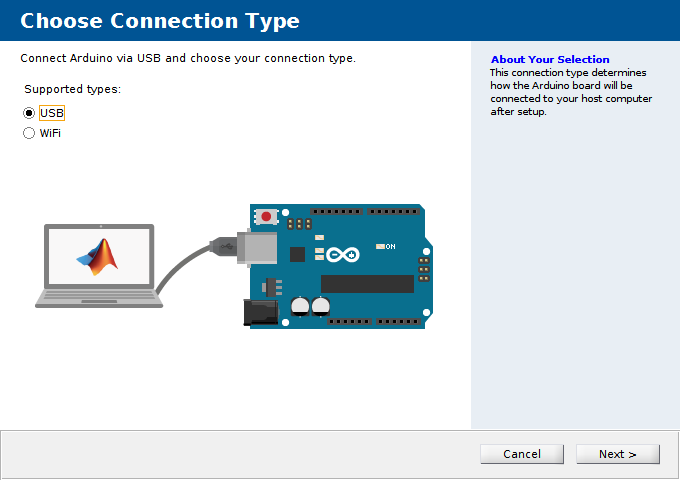

Step 2.2) Use dropdown boxes to specify the Arduino and port. If you have a lot of things plugged into USB drives in your computer you may have several ports. You will know you selected the correct port when you click the "Program" button and you see no errors and lights start flashing on your arduino.

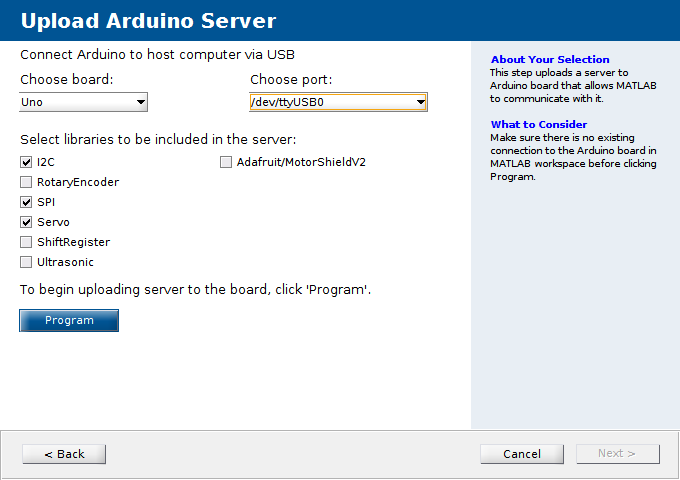

If you encounter problems, it is likely permission errors. **Try and figure it out on your own before seeking help from a classmate or professor! **This works out your brain and helps you to get to know your computer and online help forums.

After you are done, you should see the following screen. Congratulations! Your computer speaks Arduino-MATLAB-ese!

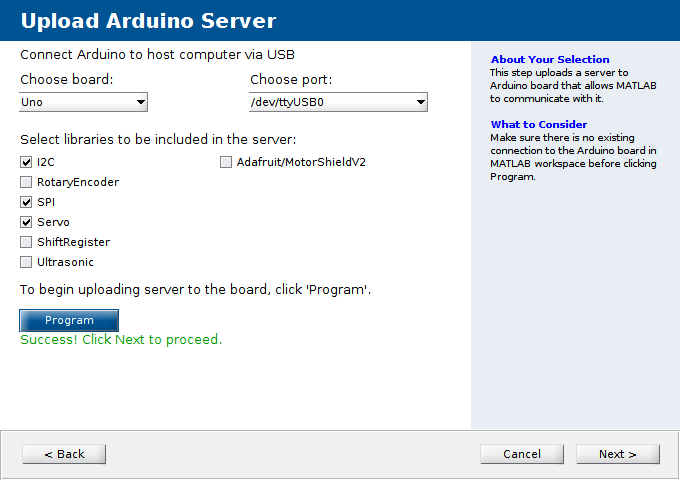

[Optional] Finally, if you would like to test and make sure that everything worked ok, MATLAB presents you with a "Test Arduino Connection" wizard. If you click "Test connection" you should get something like this out.

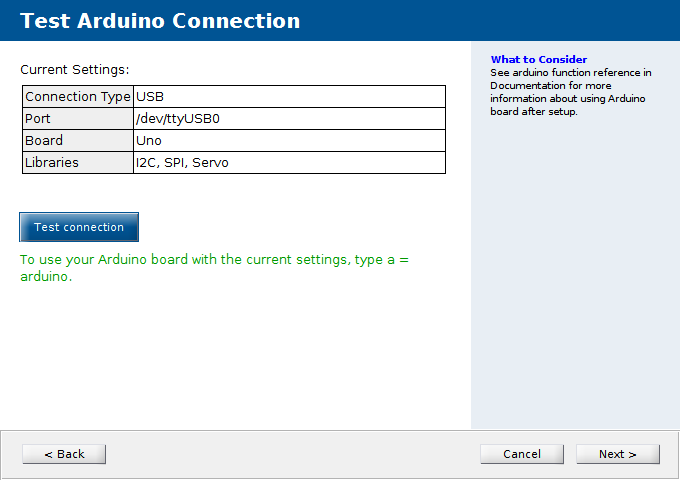

## Step 2) Let MATLAB know we want to talk to the Arduino

% Make sure to remove the arduino object from workspace every time you run your code
clear

% Setup Arduino - let the Matire D' know you would like to be seated

% Give the Arduino a name that helps user understand what it does

Cannot detect Arduino hardware. Make sure Arduino hardware is properly plugged in.

blinky_Arduino = arduino();

IF you get an error that says something like "Cannot detect Arduino hardware" do not panic! All you have to do is specify the port and the board type in the blinky_Arduino line.  It should look something like this:

Note, your port number will be different if you are on windows, macOS, or linux. Use the same port from the `arduinowizard` indicated above in step 2.

% Digital13 is the pin for the built-in LED, next lab we will use external LEDs.
ledPin = 'D13';

*Note: the *`ledPin = 'D13'` *line of code is TECHNICALLY unnecessary but helps for readability and so we don't have to keep writing *`D13`* over and over.*

## Step 3) Learn Arduino-MATLAB-ese

Ok, we have a way to talk. But we need to make sure we are speaking the same language.

In my mind, it helps to think of Arduinos as a really, really, dumb extremely good looking person.

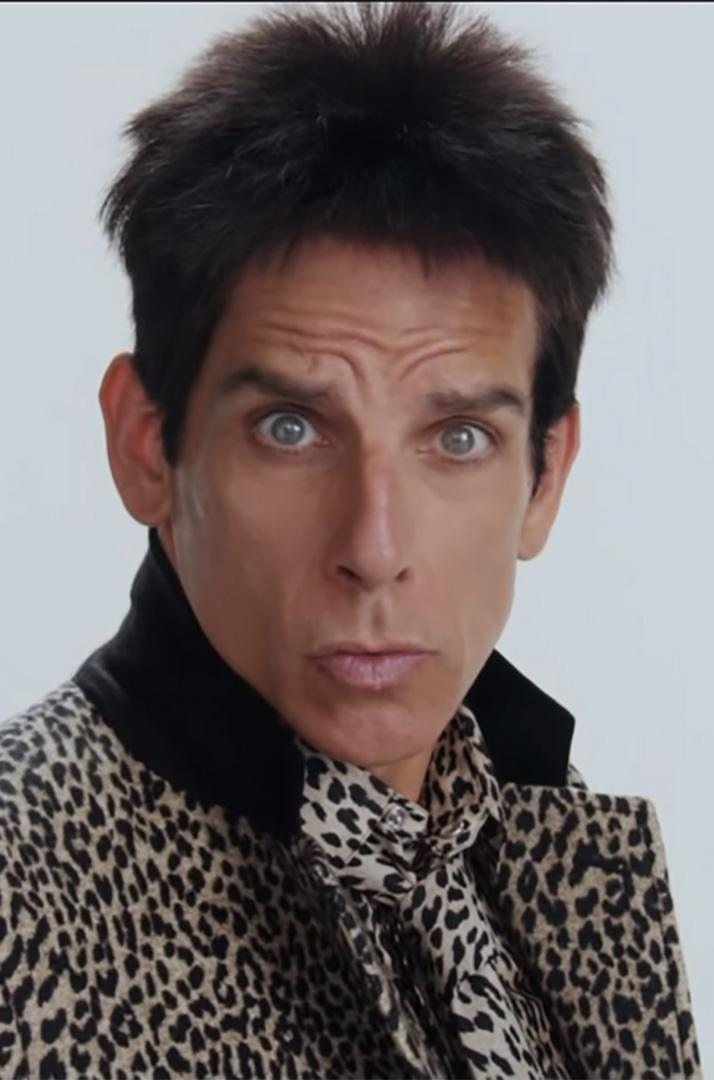

Ask Arduino (pictured above) to grab you a glass of water.

**Example 1 - Won't Work with super dumb person**)  "Good day, Arduino. This is Dr.B. Yes, my family is flourishing. How is Pat? Send my regaurds. I have found myself in quite the predicament. I am parched and without water. From one old chemist to another, would you be a gem and fetch me a glass of dihydrogen monoxide?"

**Example 2 - MIGHT work with super dumb person, but no gaurantees**) "Arduino, do as I say. From your present position, stand, walk to the kitchen. Stop after 4.2 seconds. Open the cabinet directly in front of you. Get a glass..."

Luckily for us, Arduinos aren't complicated like people. They really can only do a few things. One of the things they are best at is writing voltages to pins.

## Getting Started - Lets Blink an LED. 

% Blink LED by writing 1 (aka "on") to a pin, waiting, then turning it off.

% To turn it on, we need to write 1, to the correct location on blicky_Arduino
writeDigitalPin(blinky_Arduino, ledPin, 0);
pause(1);
writeDigitalPin(blinky_Arduino, ledPin, 1);

Alright. That is pretty much all you need for today. Understand how to turn off/on the LED and how to pause for given periods of time.

The cool thing is, you can just use MATLAB code to do programming stuff. For example, if I wanted to "blink" the LED 4 times I would:

% Blink built-in LED 10 times
writeDigitalPin(blinky_Arduino,ledPin,0);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,1);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,0);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,1);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,0);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,1);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,0);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,1);

disp('Done!')

Done!


Note: This is a terribly inefficient way to blink the led 4 times, there is a much better way that we will learn soon! If you have programmed before you probably know where this is going...

## ***BEFORE YOU MOVE ON***

**Remember: *****before you move on***** questions MUST be completed before LAs will help you.**

- Write your own pattern on a piece of paper. Try and program it.

- Change the delay timing. Does it change what you expect it to change?  

- Make sure that you can get Arduinos to work using MATLAB scripts. Idea, find a loop in a previous program and implement the blinking into a loop structure. Hint: make delays long enough to see!

# -----------------------------------------------------------------------------------------

# Lab Deliverables - Morse Code * NEED TO UPDATE NO FUNCTIONS YET!

# -----------------------------------------------------------------------------------------

With your lab partner on the opposite side of the room, you must blink a message to your partner. The LA's will distribute code words paired for your team. No talking or cell phones, what is the fun in that? Is it hard to see the built-in LED? I see two options, add extra LEDs or find a way to make it easy to see the light. You can do whatever you would like though as long as you don't talk with your partner. You can talk to the people next to you though. When you are ready, get your partners attention without talking for 1 extra credit point (awarded in good faith at LA's discretion).

To get credit, create a MATLAB script that successfully writes out your codeword. It must use calls to functions that are written **inside the script** (consequentially, only acessible to the script). We learned about how to do this on week X. Each letter should have a cooresponding function.

Example script)

% lab4_codeword.m
% NAME
% Appropriate description...etc
% NOTE: This script will not work for you, so don't copy it. 
% For illustration purposes only.

% Make sure to remove the arduino object from workspace every time you run your code
clear

% Setup Arduino - telling the Matire D' you would like to be sat
morseCode_Arduino = arduino();

% Codeword: BANANA
letter_B(morseCode_Arduino)
letter_A(morseCode_Arduino)
letter_N(morseCode_Arduino)
letter_A(morseCode_Arduino)
letter_N(morseCode_Arduino)
letter_A(morseCode_Arduino)

You then turn in your MATLAB script that writes your codeword to Canvas. As stated above** write the functions in the script file**.

Example)` letter_A` function. "A" is dot-dash in morose code so..

function letter_A(ArduinoName)
% letter_A(ArdunoName)
% Function that recreates the letter 'a' in morse code with an Arduinos 
% built in LED
%
%   Inputs:
%        ArduinoName - the name of the arduino object you created in your script
%   No Outputs*
% -----------------------------------------------------------------------------

% The builtin pin is ALWAYS 13 for Arduino Uno
ledPinNumber = 'D13';

% make sure light starts off
writeDigitalPin(ArduinoName,ledPinNumber,0);

% dot
writeDigitalPin(ArduinoName,ledPinNumber,1);
pause(0.5)
writeDigitalPin(ArduinoName,ledPinNumber,0);
pause(0.5)

% dash
writeDigitalPin(ArduinoName,ledPinNumber,1);
pause(1.5)
writeDigitalPin(ArduinoName,ledPinNumber,0);

end

% would be cool to make a dash and dot function...